# Multi-link pendulum system: Simscape modeling

Input system parameters:

%% PENDULUM PARAMETERS %%
init_angle=0   % Initial angle from vertical (degrees)

init_angle = 0

n_links=10       % Number of links 

n_links = 10


L=60;           % Total length of pendulum (cm)
W=2;            % Width of links (cm)
H=2;            % Depth of links (cm)
damping=0.0005;     % Damping factor at joints (N*m/(deg/s))
spring=0.001;    % Torsional spring constant (N*m/deg)

%% MEASUREMENT PARAMETERS %%
coord_noise_std=0.1;
angle_noise_std=0.1;

%% SIMULATION PARAMETERS %%
sim_steps = 200;
dt = 0.01;
t = [0:dt:dt*(sim_steps-1)]';
n_sims = 10;
torque_gain = 0.1;
rand_torque = torque_gain .* unifrnd(-1, 1, sim_steps * n_sims, 1);

% Resetting model to default
for i=1:19
    set_param(sprintf('pendulum_system/pendulum_links/pendulum_link_%d',i),'commented','off');
end

% Initialising number of links
for i=1:(20-n_links)
    set_param(sprintf('pendulum_system/pendulum_links/pendulum_link_%d',i),'commented','through');
end

data_len = (sim_steps-1)*n_sims

data_len = 1990


in_torque = zeros(data_len, 1);

in_ex = zeros(data_len, 1);
in_ez = zeros(data_len, 1);
in_er = zeros(data_len, 1);
in_theta = zeros(data_len, 1);

out_ex = zeros(data_len, 1);
out_ez = zeros(data_len, 1);
out_er = zeros(data_len, 1);
out_theta = zeros(data_len, 1);

in_edx = zeros(data_len, 1);
in_edz = zeros(data_len, 1);
in_edr = zeros(data_len, 1);
in_dtheta = zeros(data_len, 1);

out_edx = zeros(data_len, 1);
out_edz = zeros(data_len, 1);
out_edr = zeros(data_len, 1);
out_dtheta = zeros(data_len, 1);

% Simulate model
for sim_n=1:n_sims
    log_indices = (sim_n-1)*(sim_steps-1)+1:sim_n*(sim_steps-1);
    torque_indices = (sim_n-1)*sim_steps+1:sim_n*sim_steps;
    torque = timeseries(rand_torque(torque_indices), t);

    simout = sim("pendulum_system.slx", t);
    
    % This is quite long but hopefully clear what is being set up

    % theta = reshape(simout.pendulum_angle(1,1,:),[],1);
    theta = simout.pendulum_angle;
    % ex = reshape(simout.end_x(1,1,:),[],1);
    ex = simout.end_x;
    % ez = reshape(simout.end_z(1,1,:),[],1);
    ez = simout.end_z;
    % er = reshape(simout.end_rotation(2,1,:),[],1);
    er = simout.end_rotation;

    in_torque(log_indices) = rand_torque(torque_indices(1:length(torque_indices)-1));

    in_theta(log_indices) = theta(1:sim_steps-1);
    in_ex(log_indices) = ex(1:sim_steps-1);
    in_ez(log_indices) = ez(1:sim_steps-1);
    in_er(log_indices) = er(1:sim_steps-1);

    out_theta(log_indices) = theta(2:sim_steps);
    out_ex(log_indices) = ex(2:sim_steps);
    out_ez(log_indices) = ez(2:sim_steps);
    out_er(log_indices) = er(2:sim_steps);

    dtheta = gradient(theta);
    dex = gradient(ex);
    dez = gradient(ez);
    der = gradient(er);

    in_dtheta(log_indices) = dtheta(1:sim_steps-1);
    in_edx(log_indices) = dex(1:sim_steps-1);
    in_edz(log_indices) = dez(1:sim_steps-1);
    in_edr(log_indices) = der(1:sim_steps-1);

    out_dtheta(log_indices) = dtheta(2:sim_steps);
    out_edx(log_indices) = dex(2:sim_steps);
    out_edz(log_indices) = dez(2:sim_steps);
    out_edr(log_indices) = der(2:sim_steps);
end

nn_input = cat(2, in_theta, in_ex, in_ez, in_er, in_dtheta, in_edx, in_edz, in_edr, in_torque);
nn_targets = cat(2, out_theta, out_ex, out_ez, out_er, out_dtheta, out_edx, out_edz, out_edr);

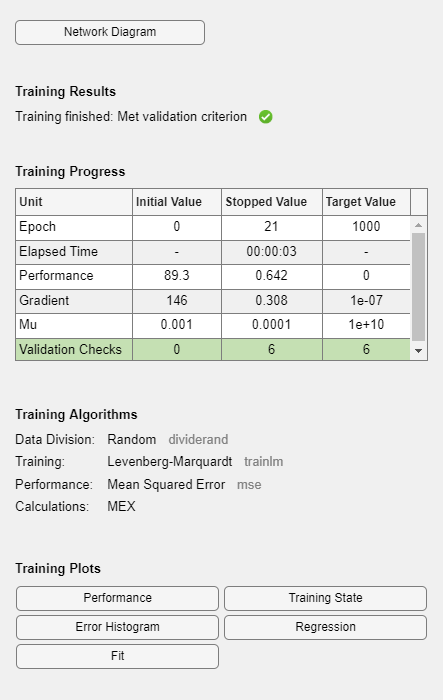

performance = 0.7838

trainPerformance = 0.7207

valPerformance = 0.8832

testPerformance = 0.9781

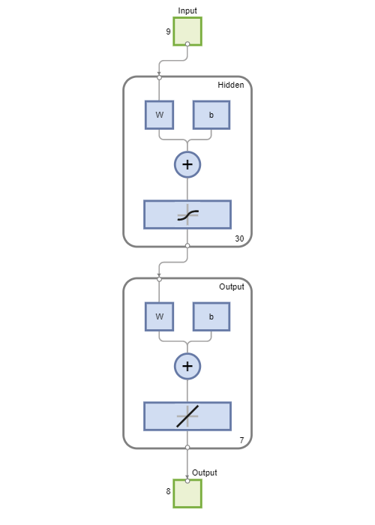

% Train the network, name it dynamics
dynamics_train